# Exercise 2 - Part A

#### Try defining the previous code from a control point of view instead of an optimizazion point of view

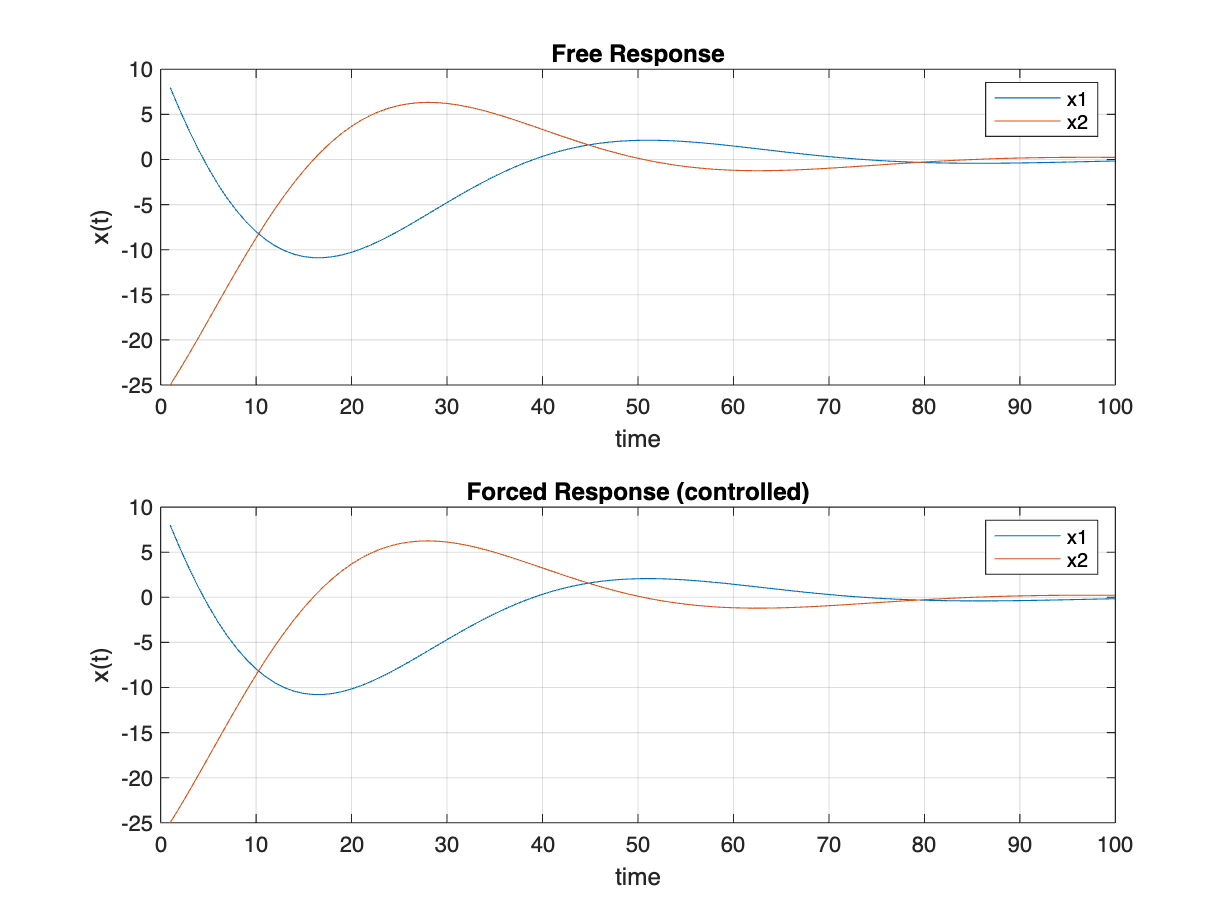

clc
clear
close all

parameters.rho = 10;
parameters.Ts=0.1;
parameters.K = 1;
parameters.M=1;
parameters.b=1;

Ts=parameters.Ts;
K=parameters.K;
M = parameters.M;
b=parameters.b;


A=[1 Ts; -K*Ts/M 1-b*Ts/M];
B=[0; Ts/M];

[parameters.n,parameters.m]=size(B);

S = eye(parameters.n);
Cz = [eye(parameters.n); zeros(parameters.m, parameters.n)];
Dz = parameters.rho .* [zeros(parameters.n, parameters.m); eye(parameters.m)];

Q = Cz' * Cz;
R = Dz' * Dz;


N=50*2;

[PP,FF]= OLQR(A,B,Q,R,S,N);

%% Simulation (free response)

x_0 = [8; -25];
x_samples = [x_0];
x_forced_samples = [x_0];

for k = 1:N-1
    x_k = A * x_samples(:,k);
    x_samples = [x_samples x_k];
    % Forced res. (controlled)
    x_k_forc = A * x_forced_samples(:,k) + B * FF{k} * x_forced_samples(:,k);
    x_forced_samples = [x_forced_samples x_k_forc];
end

% Separating state components
x1 = x_samples(1,:);
x2 = x_samples(2,:);
x1_f = x_forced_samples(1,:);
x2_f = x_forced_samples(2,:);

% Plots free and forced
figure(Name='Plots');
subplot(2,1,1);
plot(1:N, x1, 1:N, x2); 
grid on; title('Free Response'); legend('x1','x2'); xlabel('time'); ylabel('x(t)');
subplot(2,1,2);
plot(1:N, x1_f, 1:N, x2_f); 
grid on; title('Forced Response (controlled)'); legend('x1','x2'); xlabel('time'); ylabel('x(t)');

# Part B

#### Consider the time horizon *N *to be infinite.

#### Calculate the time-invariant gain matrix and validate the result.

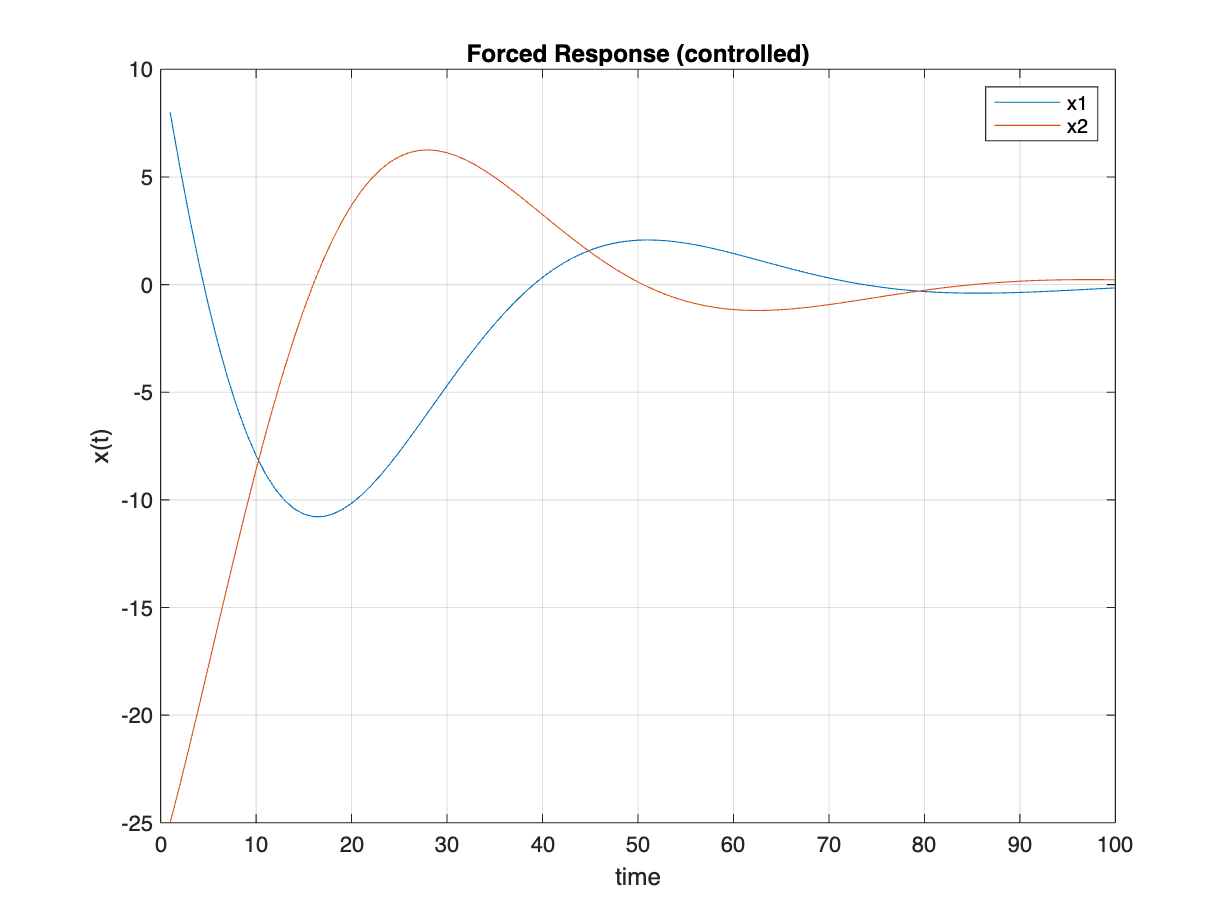

[K,S_Riccati,e] = dlqr(A,B,Q,R);

x_states = [x_0];

for k = 1:N-1
    x_k_forc = A * x_states(:,k) + B * -K * x_states(:,k);
    x_states = [x_states x_k_forc];
end

% Separating state components
x1_f_2 = x_forced_samples(1,:);
x2_f_2 = x_forced_samples(2,:);

% Plots controlled response
figure(Name='Plots');
plot(1:N, x1_f_2, 1:N, x2_f_2); 
grid on; title('Forced Response (controlled)'); legend('x1','x2'); xlabel('time'); ylabel('x(t)');

% 